# Cinematica Inversa

## Antropomorfico 3R 

### Vista Isometrica

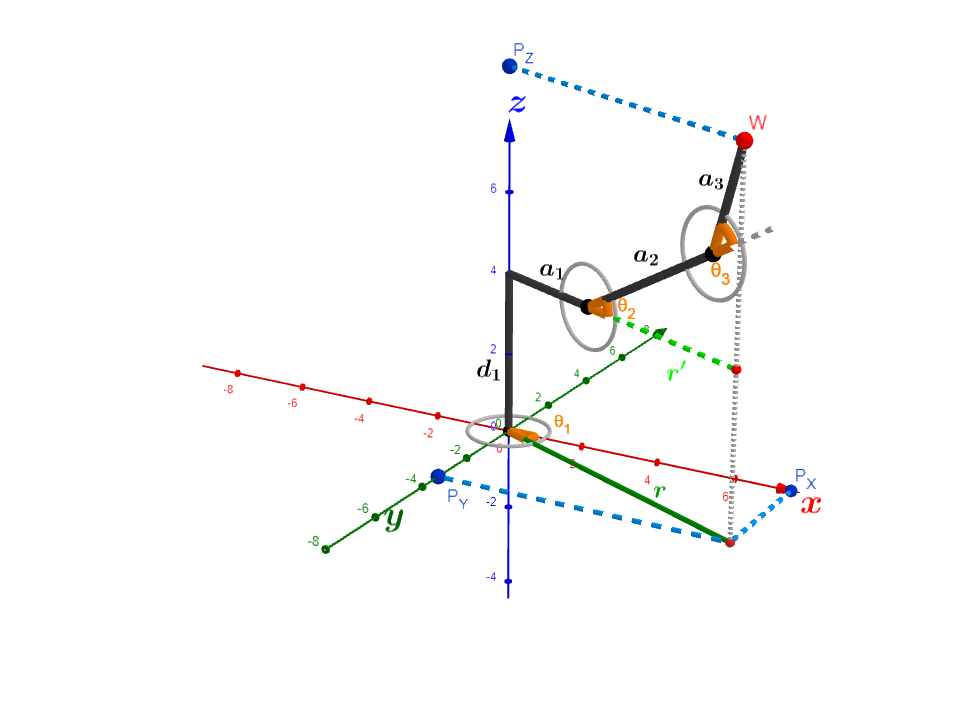

### Vista Plano ZR para θ2 y θ3

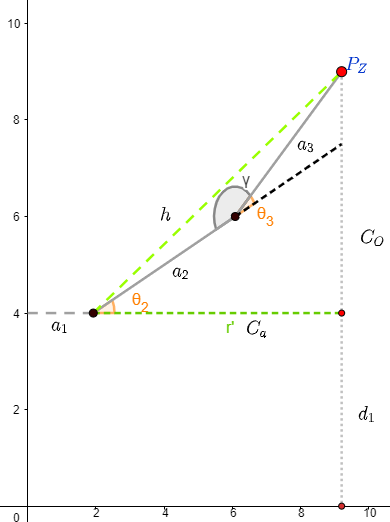

### Calculos de variables de triangulos

syms P_X P_Y P_Z a_1 a_2 a_3 d_1
alpha_1=90;
alpha_2=0;
alpha_3=0;
d_1=62.87;
d_2=0;
d_3=0;
a_1=14.5;
a_2=67.5;
a_3=88.28;
P_X=36;
P_Y=50;
P_Z=10;
W=[P_X;P_Y;P_Z]

W =     36
    50
    10


r=sqrt(P_X^2+P_Y^2);%Hipotenusa del triangulo generado desde origen al punto W en el plano XY
Ca=r-a_1;%Cateto adyacente, considerando la distancia a1 entre juntura 1-2
Co=P_Z-d_1;%Cateto opuesto, considerando la distancia d1 entre juntura 1-2
h=sqrt(Ca^2+Co^2)

h = 70.8149

#### Propiedad del coseno para cambiar Cos(**γ) a **-Cos(θ3)

#### Donde **γ=180-**θ3

#### **Cos(γ)=Cos(180-**θ3)=-Cos(θ3)

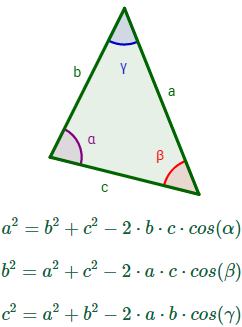

### Por Teorema De Coseno para θ3

cost3=(h^2-a_2^2-a_3^2)/(2*a_2*a_3) %Despejando del Teorema del coseno

cost3 = -0.6155

sent3=sqrt(1-cost3^2); %Propiedad trigonometrica sen^2+cos^2=1
theta_3=atan2d(sent3,cost3) %Calcularlo por medio de tangente (para todos posibles valores)

theta_3 = 127.9849

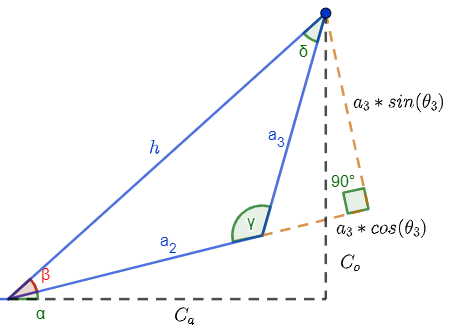

### Para  θ2=α-β 

#### Para "α" por el triangulo rectangulo comprendido entre Ca-Co 

alpha=atan2d(Co,Ca);

#### Para "β" por el triangulo rectangulo armado con a3 

Ca2=a_2+a_3*cosd(theta_3);%Cateto adyacente
Co2=a_3*sind(theta_3);%Cateto opuesto
beta=atan2d(Co2,Ca2);
theta_2=alpha-beta

theta_2 = -127.5800

### Vista Plano XY Para θ1

####  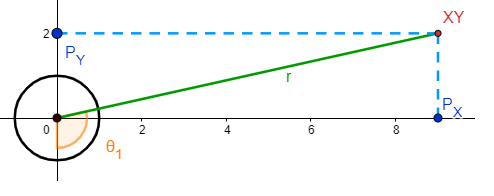

theta_1=atan2d(P_Y,P_X)

theta_1 = 54.2461


A01=parametros(theta_1, d_1, alpha_1, a_1)

A01 =     0.5843         0    0.8115    8.4724
    0.8115         0   -0.5843   11.7672
         0    1.0000         0   62.8700
         0         0         0    1.0000


A12=parametros(theta_2, d_2, alpha_2, a_2)

A12 =    -0.6099    0.7925         0  -41.1661
   -0.7925   -0.6099         0  -53.4939
         0         0    1.0000         0
         0         0         0    1.0000


A23=parametros(theta_3, d_3, alpha_3, a_3)

A23 =    -0.6155   -0.7882         0  -54.3323
    0.7882   -0.6155         0   69.5799
         0         0    1.0000         0
         0         0         0    1.0000



As=A01*A12*A23

As =     0.5843   -0.0041    0.8115   36.0000
    0.8115   -0.0057   -0.5843   50.0000
    0.0071    1.0000         0   10.0000
         0         0         0    1.0000


if (round(As(1:3,4),0)==W)
    disp("Funciona")
else
    disp("Solución no viable")
end

Funciona


## Scara P3R

### Vista Isometrica

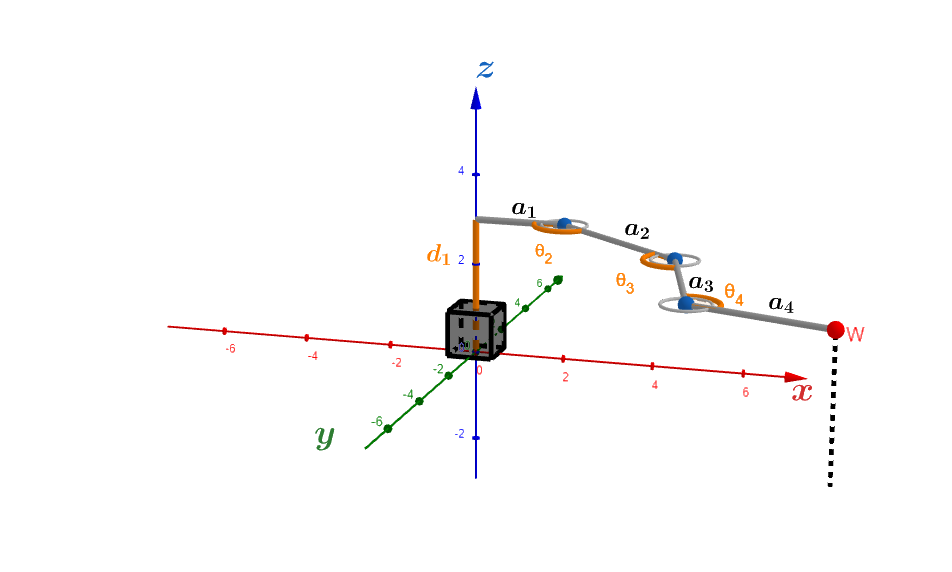

### Vista Superior

*Se forma el ****Triangulo Oblicuo**** para aplicar ****teorema de Cos**** y resolver por ****metodos geometricos***

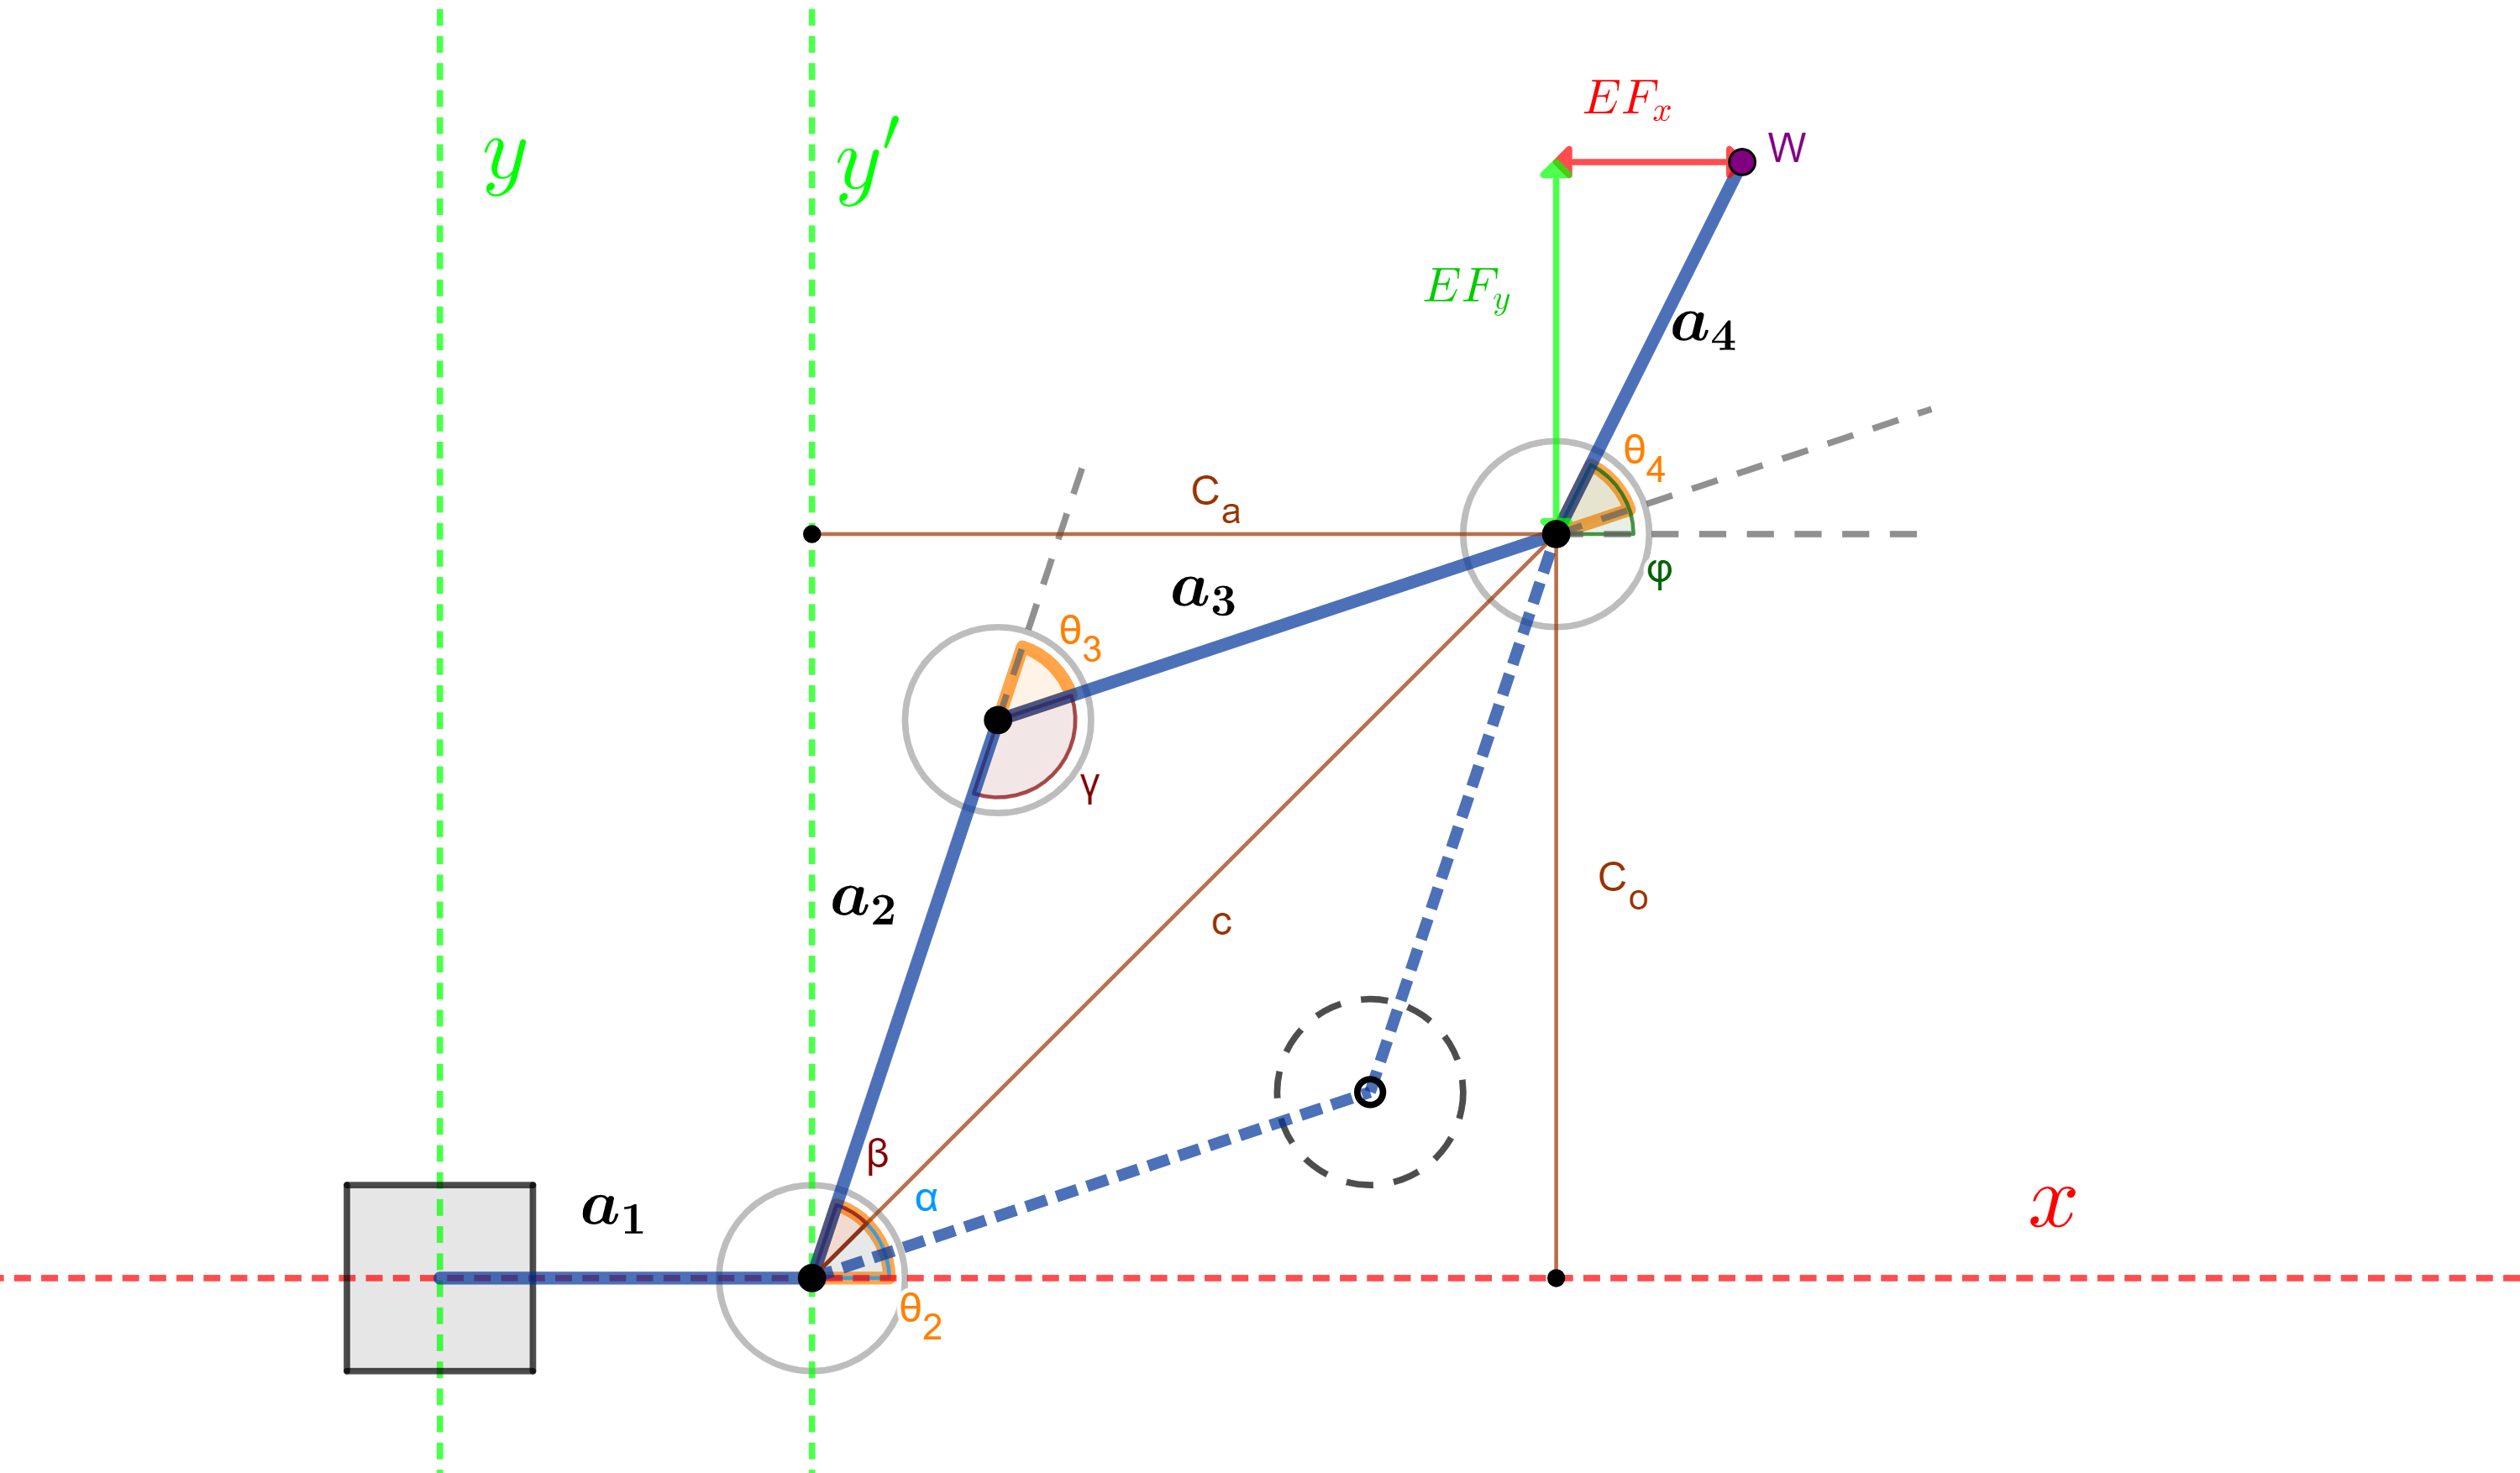

#### **Cos(γ)=Cos(180-**θ3)=-Cos(θ3)

syms P_X P_Y P_Z a_1 a_2 a_3 a_4 d_1 %Variables simbolicas para las ecuaciones de manera simbolica

#### Parametros conocidos (Distancias y rotaciones)

theta_1=0; %Angulos θ
alpha_1=0;alpha_2=0;alpha_3=0;alpha_4=0; %Angulos α
d_2=0;d_3=0;d_4=0;%Distancias en z
%Distacias en x
a_1=47.3;
a_2=149.1;
a_3=148.8;
a_4=30;

#### Parametros ingresados (Posición y Orientacion)

P_X=17; %Punto en X
P_Y=26; %Punto en Y
P_Z=120; %Punto en Z
phi=34; %Angulo de orientación
W=[P_X;P_Y;P_Z] %Vector de Posición

W =     17
    26
   120


Calculo de **"c":** ***Hipotenusa**** del ****triangulo rectangulo**** formado en ****X-Y';*** ***Base**** de ****triangulo Oblicuo****.*

EFx=cosd(phi)*a_4; %Distancia en "x" entre punto W y Join4

EFx = 24.8711

EFy=sind(phi)*a_4; %Distancia en "y" entre punto W y Join4

EFy = 16.7758

Ca=P_X-EFx-a_1;    %Cateto Adyacente del triangulo formado en X-Y'
Co=P_Y-EFy;        %Cateto Opuesto del triangulo formado en X-Y'
c=sqrt(Ca^2+Co^2) %Hipotenusa del triangulo rectangulo formado en X-Y'; Base de triangulo Oblicuo.

c = 55.9369

### Por Teorema De Coseno para θ3

theta_3=acosd((c^2-a_2^2-a_3^2)/(2*a_2*a_3))

theta_3 = 158.3549

***Codo arriba****=-acosd((c^2-a_2^2-a_3^2)/(2*a_2*a_3))*

***Codo abajo****=acosd((c^2-a_2^2-a_3^2)/(2*a_2*a_3))*

#### Otra Opcion para calcular  θ3

% cost3=(c^2-a_2^2-a_3^2)/(2*a_2*a_3)%Aplicando teorema de ceseno
% sent3=sqrt(1-cost3^2); %Propiedad trigonometrica sen^2+cos^2=1
% theta_3=atan2d(sent3,cost3) %Calcularlo por medio de tangente

### Para  θ2=α-β 

*Para ****"α"**** por el**** triangulo rectangulo**** comprendido entre ****X-Y' (Ca-Co)***

alpha=atan2d(Co,Ca);

*Para ****"β"**** por el ****teorema del coseno***

beta=acosd((a_2^2+c^2-a_3^2)/(2*a_2*c));
theta_2=alpha-beta

theta_2 = 91.6327

***Codo arriba****=alpha+beta*

***Codo abajo****=alpha-beta*

### Para  θ4=ϕ-θ2-θ3

*Se debe ****conocer el valor**** de ****ϕ**** (****Orientación**** a la que está el ****punto "w"**** de la ****base****)*

theta_4=phi-theta_2-theta_3

theta_4 = -215.9876

### Para  d1 (Distancia en el eje Z)=Pz

d_1=P_Z

d_1 = 120

### Comprobación

A01=parametros(theta_1, d_1, alpha_1, a_1)

A01 =     1.0000         0         0   47.3000
         0    1.0000         0         0
         0         0    1.0000  120.0000
         0         0         0    1.0000


A12=parametros(theta_2, d_2, alpha_2, a_2)

A12 =    -0.0285   -0.9996         0   -4.2483
    0.9996   -0.0285         0  149.0395
         0         0    1.0000         0
         0         0         0    1.0000


A23=parametros(theta_3, d_3, alpha_3, a_3)

A23 =    -0.9295   -0.3689         0 -138.3075
    0.3689   -0.9295         0   54.8859
         0         0    1.0000         0
         0         0         0    1.0000


A34=parametros(theta_4, d_4, alpha_4, a_4)

A34 =    -0.8091   -0.5876         0  -24.2743
    0.5876   -0.8091         0   17.6283
         0         0    1.0000         0
         0         0         0    1.0000



As=A01*A12*A23*A34

As =     0.8290   -0.5592         0   17.0000
    0.5592    0.8290         0   26.0000
         0         0    1.0000  120.0000
         0         0         0    1.0000


if (round(As(1:3,4),0)==W)
    disp("Solución viable")
else
    disp("Solución no viable")
end

Solución viable


## Condiciones de desacople cinematico:

3 Ejes de rotacion consecutivos se intersecten en un punto "W" (Muñeca Esferica)

3 Ejes de rotacion consecutivos sean paralelos 

### Resolver Muñeca:

#### Se parte de la matriz de rotacion

Se extrae la matriz de rotacion de la cinematica directa de R36

La orientacion corresponde a angulos de Euler ZYZ

Rz(T4)*Ry(T5)*Rz(T6)

Despejamos de la matriz de rotacion los angulos 

Calcular Pw con el punto del efector final

Pw=Pe-d6*R6

function Matriz_DH=DH(n,matriz)%Funcion Para Matriz DH (Final)
    Matriz_T=eye(4);
    for i=1:n
        angz=matriz(i,1);
        d=matriz(i,2);
        angx=matriz(i,3);
        a=matriz(i,4);        
        Matriz_S=parametros(angz,d,angx,a); %Matrices DH Por Eslabon (A01, A12....)
        Matriz_T=Matriz_T*Matriz_S; %Matrices DH PostMultiplicacion (A01*A12,A01*A12*A23...)
    end
    Matriz_DH=Matriz_T;  %Matriz DH (A01*....A(n-1,n))
end
function Homogenea=parametros(angz,d,angx,a)%Calculo de la Matriz homogenea de DH (por eslabon)
    Homogenea=[cosd(angz), -sind(angz)*cosd(angx), sind(angz)*sind(angx), a*cosd(angz);
        sind(angz), cosd(angz)*cosd(angx), -cosd(angz)*sind(angx), a*sind(angz);
        0, sind(angx), cosd(angx), d;
        0, 0, 0, 1;];
end
function Tabla_DH=T_DH(i,matrix) %Funcion para Tabla de Parametros DH
    syms theta_n a_n alpha_n d_n
    T=[sym('theta_%d',[1 i])];
    d=[sym('d_%d',[1 i])];
    A=[sym('alpha_%d',[1 i])];
    a=[sym('a_%d',[1 i])];
    Tabla_D=[transpose(T) transpose(d) transpose(A) transpose(a)];
    for j=1:i
        for k=1:4
            if (matrix(j,k)~=1 && matrix(j,k)~=0)
                Tabla_D(j,k)=1;
            end
        end        
    Tabla_T(j,:)=Tabla_D(j,:).*matrix(j,:);
    end
    Tabla_DH=[theta_n d_n alpha_n a_n;Tabla_T];
end